# Multi-Domain Heat Transfer with Non-Linear Insulator

Assumptions:

- 300 mm^2 aluminium conductor

- 8mm thickness insulator

- surrounding sand, properties estimated

- surrounding dirt, properties estimated

- cable initial temperature 14C

- soil temperature 14C

- Cable power dissipation based on Ohm's Law

clearvars
close all

% Constants
kToC = 273.3;
tSoil = 14;
tCable = tSoil; % Initially
cableArea = 300 / 1e6; % 300mm^2 in m^2

## Create the Geometry

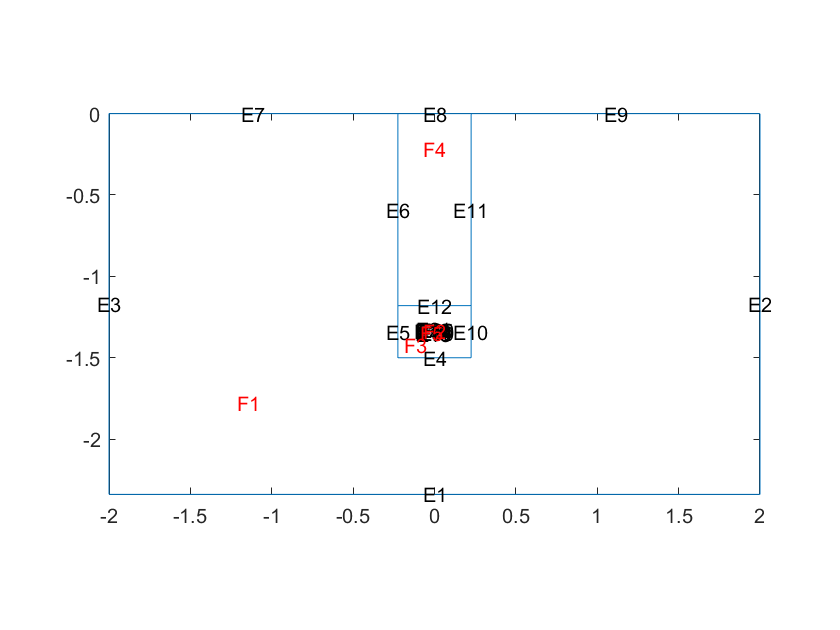

dl = generateGeom_Insulator();

figure
pdegplot(dl,'EdgeLabels','on','SubdomainLabels','on')
axis equal

% Set some constants, which are read by hand from the figure
% Face indices
faceSoil = 1;
faceCond = 2;
faceSand = 3;
faceTrench = 4;
faceInsul = 5;

% Edge groups:
edgeSoil = 1:1:3;
edgeAir = 7:1:9;

## Set up Empty Thermal Model and Mesh

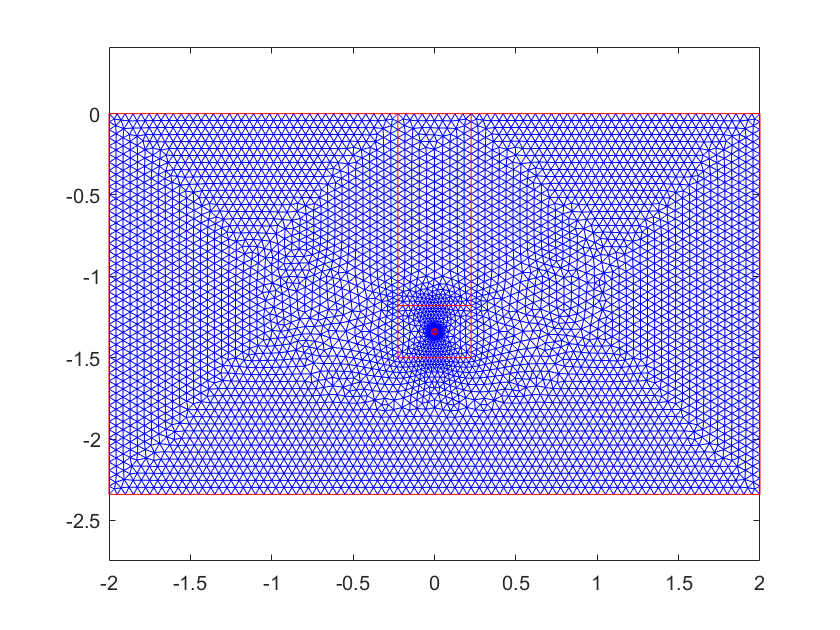

thermalmodel = createpde('thermal', 'transient');
geometryFromEdges(thermalmodel, dl);
generateMesh(thermalmodel,...
    'Hgrad', 1.1,...
    'Hmax', 0.05, ...
    'Hmin', 0.0001);

figure
pdeplot(thermalmodel)

## Set Thermophysical Constant Properties

Soil properties are assumptions in SI units

### Material Properties

% Outer soil
thermalProperties(thermalmodel,...
    'Face', faceSoil, ...
    'ThermalConductivity', 0.2, ...
    'MassDensity', 2000 , ...
    'SpecificHeat', 0.290);

%Inner sand, saturated
thermalProperties(thermalmodel,...
    'Face', faceSand, ...
    'ThermalConductivity', 2.0, ...
    'MassDensity', 1000 , ...
    'SpecificHeat', 0.290);

% Trench backfill
thermalProperties(thermalmodel,...
    'Face', faceTrench, ...
    'ThermalConductivity', 1, ...
    'MassDensity', 1000 , ...
    'SpecificHeat', 0.290);

### Boundary Conditions

thermalBC(thermalmodel, ....
    'Edge', [edgeSoil edgeAir], ...
    'Temperature', tSoil + kToC);

### Initial Conditions

% Set initial conditions
thermalIC(thermalmodel, ...
    tSoil + kToC);

## Set Up The Conductor and Insulator

### Cable

% Cable parameters
cableState.I = 400; % Amps
cableState.Area = cableArea;

thermalProperties(thermalmodel,...
    'Face', faceCond, ...
    'ThermalConductivity', 237, ...
    'MassDensity', 2700, ...
    'SpecificHeat', 900);

internalHeatSource(thermalmodel, ...
    @(r,s) powerFromResistivity(r, s, cableState), ...
    'Face', faceCond);

### Insulator

Assume non-linear thermal conductivity of the XLPE insulator

thermalProperties(thermalmodel,...
    'Face', faceInsul, ...
    'ThermalConductivity', @xlpeConductivity, ...
    'MassDensity', 2700, ...
    'SpecificHeat', 900);

## Solve

Setting up the solution time vector in seconds first, then run.

tlist = 0:50:20000;
R = solve(thermalmodel,tlist);

## Plot

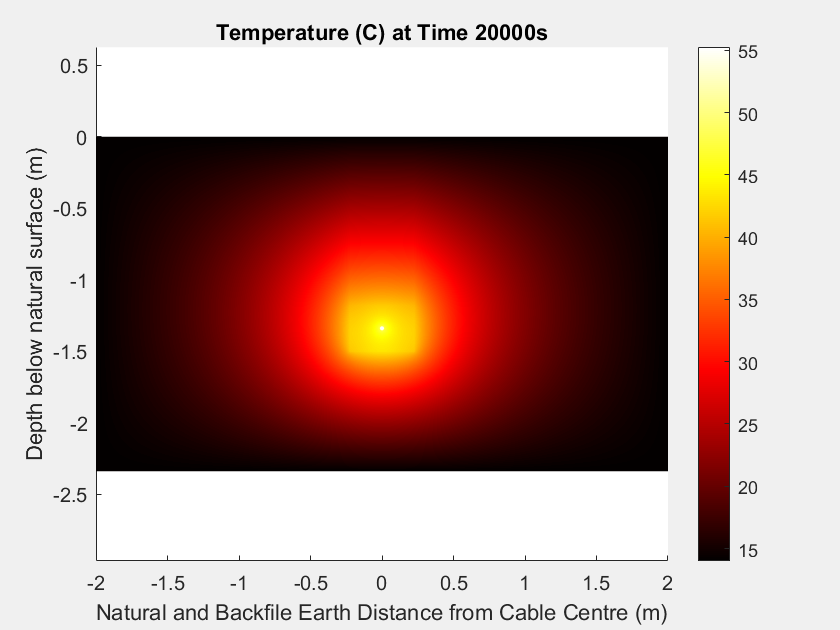

showAnim = true;
if showAnim
    h = figure; %#ok<*UNRCH>
    set(h,'Visible','on')
    for i = 1:numel(tlist)
        plotPDE(thermalmodel, R, tlist, kToC, i)
        M(i) = getframe; %#ok<*SAGROW>
    end
else
    plotPDE(thermalmodel, R, tlist, kToC,...
        size(R.Temperature, 2))
end

Copyright © 2021 The MathWorks, Inc.